close all; clc

syms lambda
syms x1 x2 real
syms a b positive
f1 = a - x1 - 4*x1*x2/(1+x1^2);
f2 = b*x1*(1 - x2/(1+x1^2));

sln = solve([f1 f2], [x1 x2])

sln = struct with fields:
    x1: a/5
    x2: a^2/25 + 1



J = jacobian([f1 f2], [x1 x2]);
J = 25*(a^2/25 + 1)*J;
A = simplify(subs(J, [x1 x2], [sln.x1 sln.x2]))

$$A = \left(\begin{array}{cc} 3\,a^{2}-125 & -20\,a\\ 2\,a^{2}\,b & -5\,a\,b \end{array}\right)$$

det(A - lambda*eye(2))

$$ans = 25\,b\,a^{3}-3\,a^{2}\,\lambda +5\,b\,a\,\lambda +625\,b\,a+\lambda^{2}+125\,\lambda$$

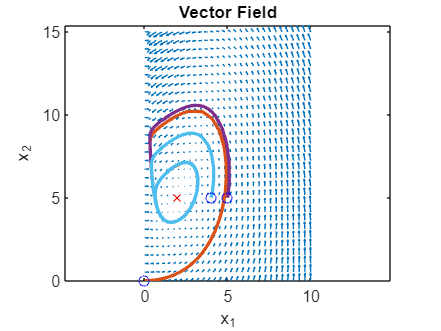

% Create vector field
close all;
x = linspace(0,10,30);
y = linspace(0,15,30);
[X,Y] = meshgrid(x,y);

a = 10;
b = 2;

DX = a - X - 4.*X.*Y./(1+X.^2);                 
DY = b*X.*(1 - Y./(1+X.^2));

quiver(X,Y,DX,DY,1);
xlabel('x_1')
ylabel('x_2')
axis equal;
title("Vector Field")

hold on; 
f= @(t,P) [a - P(1) - 4.*P(1).*P(2)./(1+P(1).^2); ...
    b*P(1).*(1 - P(2)./(1+P(1).^2))];
x1_0 = [0 5 4];
x2_0 = [0 5 5];
for i = 1:numel(x1_0)
    [t,s] = ode45(f,[0 30], [x1_0(i) x2_0(i)]);
    plot(s(:,1),s(:,2),'LineWidth',2)
    plot(x1_0(i), x2_0(i), 'bo')
end
plot(a/5, 1+a^2/25, 'rx')
hold off 